This script examines tuning curve shape under high and low contrast for current clamp recordings. Before including a cell in this analysis, you must first complete the following steps:

- Label high contrast epochs with suffix '_SP10_ff'

- Label low contrast epochs with suffix '_SP10_Intensity0d1' (this is spefically for epochs where bar intensity was 0d1)

- Run the preprocessing script for this analysis: Preprocessing_CurrentClampManyContrasts.m located in C:\Users\mrsco\Box\Completed_Analysis\WholeCell\ManyContrasts

- Use the ExtractVms app to extract underlying membrane potentials from each epoch. The results should be saved to the same folder that is made by the preprocessing app.

Then you're ready to go

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name shosuld be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'CurrentClamp', 'PotassiumSpikes', '_ff'};
mustHave_2b = {'CurrentClamp', 'PotassiumSpikes', '_Intensity0d1'};
cantHave_1 = [];
cantHave_2 = {'Cesium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

dataLocation = 'C:\Users\mrsco\Box\Completed_Analysis\WholeCell\ManyContrasts';

upFFSpikeFailures= [];
upLowCSpikeFailures = [];
upFFSpikeDSI = [];
upLowCSpikeDSI = [];
upFFSpikeNormedArea = [];
upLowCSpikeNormedArea = [];
upFFSpikeArea = [];
upLowCSpikeArea = [];
upFFVmDSI = [];
upLowCVmDSI = [];
upFFVmNormedArea = [];
upLowCVmNormedArea = [];
upFFVmArea = [];
upLowCVmArea = [];
upNames = {};
for i = 1:size(ups)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_lowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass || pass_LowC
        continue
    end
    
    cname = struct_i.cellID;
    folderName = [dataLocation, '\', cname];
    
    
    if ~exist(folderName, 'dir')
        disp(['Vms have not been isolated for ' cname '. Run Preprocessing_CurrentClampManyContrasts.m to create the folder. Then use ExtractVms' ...
            '.mlapp to extract Vm traces' '...Skipping cell for now.'])
        continue
    end
    
    %load the Vm traces that have already been isolated
    try
        load(fullfile(folderName, 'ff_extractedVms.mat')); %loads varaible called 'extractedTraces'
        ffTraces = extractedTraces;
        load(fullfile(folderName, 'Intensity0d1_extractedVms.mat'));
        LowCTraces = extractedTraces;
    catch
        disp(['It looks like you have not extracted all the Vms for cell ' cname '. Run Preprocessing_CurrentClampManyContrasts.m and ExtractVms.mlapp to do so'...
            ' ...Skipping cell for now'])
        continue
    end
    
    directions_ff = loc.Analysis_Results.orientationByEpoch;
    directions_lowC = loc_lowC.Analysis_Results.orientationByEpoch;
    
    ffVmOutput = VmCurrentInjection_Helper(ffTraces, directions_ff);
    lowCVmOutput = VmCurrentInjection_Helper(LowCTraces, directions_lowC);
    
    upFFVmDSI(end + 1) = ffVmOutput.DSI_MaxResponses;
    upLowCVmDSI (end + 1) = lowCVmOutput.DSI_MaxResponses;
    upFFVmNormedArea (end + 1) = ffVmOutput.NormalizedArea_MaxResponses;
    upLowCVmNormedArea (end + 1) = lowCVmOutput.NormalizedArea_MaxResponses;
    upFFVmArea (end + 1) = ffVmOutput.TotalArea_MaxResponses;
    upLowCVmArea (end + 1) = lowCVmOutput.TotalArea_MaxResponses;
    
    ffSpikeOutput = SpikeMetricHelper(loc);
    lowCSpikeOutput = SpikeMetricHelper(loc_lowC);
    
    upFFSpikeFailures(end + 1) = ffSpikeOutput.failure;
    upLowCSpikeFailures(end + 1) = lowCSpikeOutput.failure;
    upFFSpikeDSI(end + 1) = ffSpikeOutput.DSI;
    upLowCSpikeDSI (end + 1) = lowCSpikeOutput.DSI;
    upFFSpikeNormedArea (end + 1) = ffSpikeOutput.NormalizedTuningCurveArea;
    upLowCSpikeNormedArea (end + 1) = lowCSpikeOutput.NormalizedTuningCurveArea;
    upFFSpikeArea (end + 1) = ffSpikeOutput.TuningCurveArea;
    upLowCSpikeArea (end + 1) = lowCSpikeOutput.TuningCurveArea;
    
    upNames{end + 1} = struct_i.cellID;
end


downFFSpikeFailures= [];
downLowCSpikeFailures = [];
downFFSpikeDSI = [];
downLowCSpikeDSI = [];
downFFSpikeNormedArea = [];
downLowCSpikeNormedArea = [];
downFFSpikeArea = [];
downLowCSpikeArea = [];
downFFVmDSI = [];
downLowCVmDSI = [];
downFFVmNormedArea = [];
downLowCVmNormedArea = [];
downFFVmArea = [];
downLowCVmArea = [];
downNames = {};
for i = 1:size(downs)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_lowC, pass_LowC] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2b, cantHave_2, rigMandates);
    
    if pass || pass_LowC
        continue
    end
    
    cname = struct_i.cellID;
    folderName = [dataLocation, '\', cname];
    
    
    if ~exist(folderName, 'dir')
        disp(['Vms have not been isolated for ' cname '. Run Preprocessing_CurrentClampManyContrasts.m to create the folder. Then use ExtractVms' ...
            '.mlapp to extract Vm traces' '...Skipping cell for now.'])
        continue
    end
    
    %load the Vm traces that have already been isolated
    try
        load(fullfile(folderName, 'ff_extractedVms.mat')); %loads varaible called 'extractedTraces'
        ffTraces = extractedTraces;
        load(fullfile(folderName, 'Intensity0d1_extractedVms.mat'));
        LowCTraces = extractedTraces;
    catch
        disp(['It looks like you have not extracted all the Vms for cell ' cname '. Run Preprocessing_CurrentCLampManyContrasts.m and ExtractVms.mlapp to do so'...
            ' ...Skipping cell for now'])
        continue
    end
    
    directions_ff = loc.Analysis_Results.orientationByEpoch;
    directions_lowC = loc_lowC.Analysis_Results.orientationByEpoch;
    
    ffVmOutput = VmCurrentInjection_Helper(ffTraces, directions_ff);
    lowCVmOutput = VmCurrentInjection_Helper(LowCTraces, directions_lowC);
    
    downFFVmDSI(end + 1) = ffVmOutput.DSI_MaxResponses;
    downLowCVmDSI (end + 1) = lowCVmOutput.DSI_MaxResponses;
    downFFVmNormedArea (end + 1) = ffVmOutput.NormalizedArea_MaxResponses;
    downLowCVmNormedArea (end + 1) = lowCVmOutput.NormalizedArea_MaxResponses;
    downFFVmArea (end + 1) = ffVmOutput.TotalArea_MaxResponses;
    downLowCVmArea (end + 1) = lowCVmOutput.TotalArea_MaxResponses;
    
    ffSpikeOutput = SpikeMetricHelper(loc);
    lowCSpikeOutput = SpikeMetricHelper(loc_lowC);
    
    downFFSpikeFailures(end + 1) = ffSpikeOutput.failure;
    downLowCSpikeFailures(end + 1) = lowCSpikeOutput.failure;
    downFFSpikeDSI(end + 1) = ffSpikeOutput.DSI;
    downLowCSpikeDSI (end + 1) = lowCSpikeOutput.DSI;
    downFFSpikeNormedArea (end + 1) = ffSpikeOutput.NormalizedTuningCurveArea;
    downLowCSpikeNormedArea (end + 1) = lowCSpikeOutput.NormalizedTuningCurveArea;
    downFFSpikeArea (end + 1) = ffSpikeOutput.TuningCurveArea;
    downLowCSpikeArea (end + 1) = lowCSpikeOutput.TuningCurveArea;
    
    downNames{end + 1} = struct_i.cellID;
end


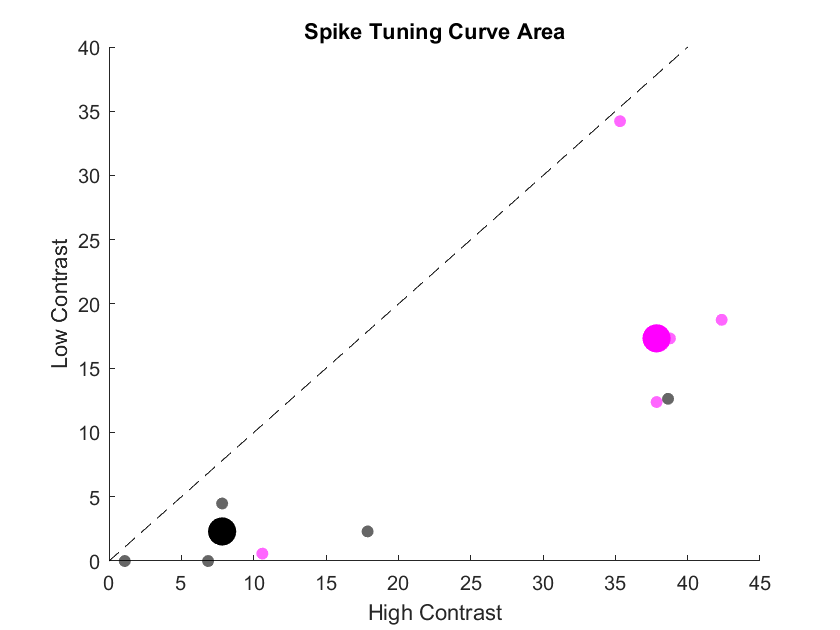

figure
title('Spike Tuning Curve Area')
hold on
scatter(upFFSpikeArea, upLowCSpikeArea, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(upFFSpikeArea), median(upLowCSpikeArea), 200, 'k', 'filled')
scatter(downFFSpikeArea, downLowCSpikeArea, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(median(downFFSpikeArea), median(downLowCSpikeArea), 200, 'm', 'filled')
plot([0, 40], [0, 40], '--k')
xlabel('High Contrast')
ylabel('Low Contrast')

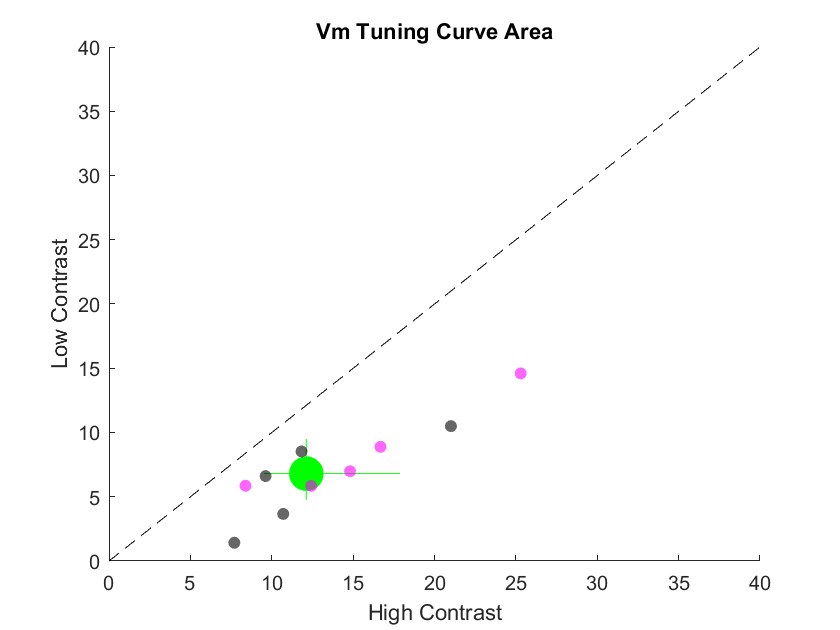

medianX = median([upFFVmArea, downFFVmArea]);
medianY = median([upLowCVmArea, downLowCVmArea]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upFFVmArea, downFFVmArea], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upLowCVmArea, downLowCVmArea], 10000);


figure
title('Vm Tuning Curve Area')
hold on
plot([0, 40], [0, 40], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')

scatter(upFFVmArea, upLowCVmArea, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downFFVmArea, downLowCVmArea, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')

p = signrank([upFFVmArea, downFFVmArea], [upLowCVmArea, downLowCVmArea])

p = 0.0020

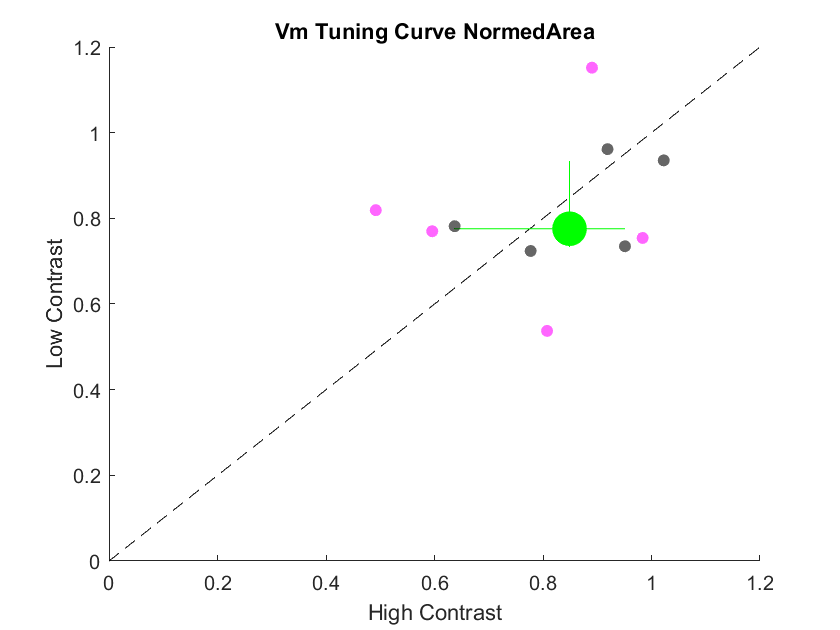

medianX = median([upFFVmNormedArea, downFFVmNormedArea]);
medianY = median([upLowCVmNormedArea, downLowCVmNormedArea]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upFFVmNormedArea, downFFVmNormedArea], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upLowCVmNormedArea, downLowCVmNormedArea], 10000);

figure
title('Vm Tuning Curve NormedArea')
hold on
plot([0, 1.2], [0, 1.2], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')

scatter(upFFVmNormedArea, upLowCVmNormedArea, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downFFVmNormedArea, downLowCVmNormedArea, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 1.2])
ylim([0, 1.2])

p = signrank([upFFVmNormedArea, downFFVmNormedArea], [upLowCVmNormedArea, downLowCVmNormedArea])

p = 1

%proportion over unity for chi squared test with spikes:
overUnity_NormedArea = [upFFVmNormedArea downFFVmNormedArea] > [upLowCVmNormedArea, downLowCVmNormedArea];
proportion_NormedArea = sum(overUnity_NormedArea)/numel(overUnity_NormedArea)

proportion_NormedArea = 0.5000

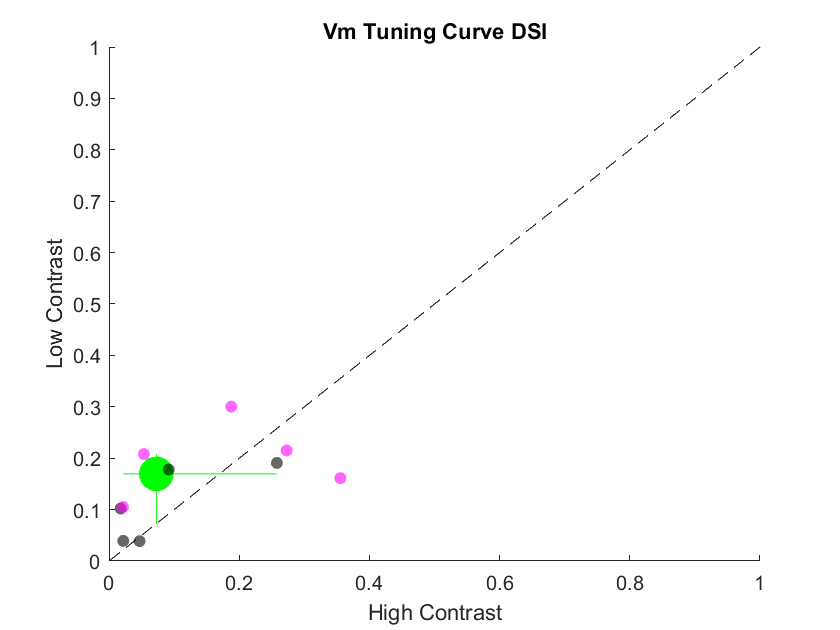

medianX = median([upFFVmDSI, downFFVmDSI]);
medianY = median([upLowCVmDSI, downLowCVmDSI]);
[~, ~, xER1, xER2] = medianCI95Bootstrap([upFFVmDSI, downFFVmDSI], 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap([upLowCVmDSI, downLowCVmDSI], 10000);


figure
title('Vm Tuning Curve DSI')
hold on
plot([0, 1.3], [0, 1.3], '--k')
scatter(medianX, medianY, 300, 'filled', 'g')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'g')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'g')

scatter(upFFVmDSI, upLowCVmDSI, 'k', 'filled', 'MarkerFaceAlpha', 0.6)
scatter(downFFVmDSI, downLowCVmDSI, 'm', 'filled', 'MarkerFaceAlpha', 0.6)
xlabel('High Contrast')
ylabel('Low Contrast')
xlim([0, 1])
ylim([0, 1])

p = signrank([upFFVmDSI, downFFVmDSI], [upLowCVmDSI, downLowCVmDSI])

p = 0.3750

%proportion over unity for chi squared test with spikes:
overUnity_DSI = [upFFVmDSI downFFVmDSI] > [upLowCVmDSI, downLowCVmDSI];
proportion_DSI = sum(overUnity_DSI)/numel(overUnity_DSI)

proportion_DSI = 0.4000

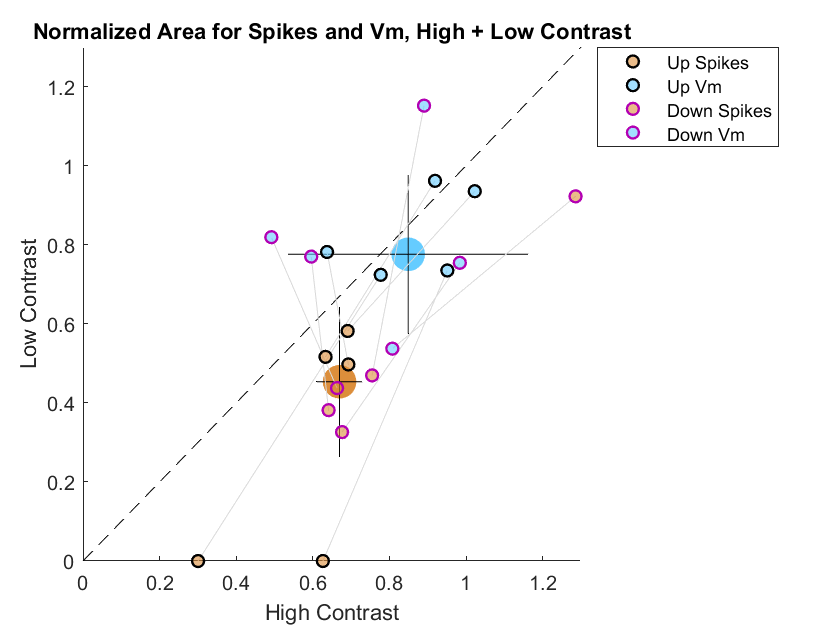



medianSpikeX = median([upFFSpikeNormedArea, downFFSpikeNormedArea]);
medianSpikeY = median([upLowCSpikeNormedArea downLowCSpikeNormedArea]);
xSpikeER = iqr([upFFSpikeNormedArea, downFFSpikeNormedArea]);
ySpikeER = iqr([upLowCSpikeNormedArea downLowCSpikeNormedArea]);

medianVmX = median([upFFVmNormedArea, downFFVmNormedArea]);
medianVmY = median([upLowCVmNormedArea, downLowCVmNormedArea]);
xVmER = iqr([upFFVmNormedArea, downFFVmNormedArea]);
yVmER = iqr([upLowCVmNormedArea, downLowCVmNormedArea]);


figure
title('Normalized Area for Spikes and Vm, High + Low Contrast')
hold on

%Scatter medians for spikes and Vm
scatter(medianSpikeX, medianSpikeY, 300, 'MarkerEdgeColor', [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [220, 142, 59]/255, 'HandleVisibility', 'off') %spike median
plot([-xSpikeER, xSpikeER]+medianSpikeX, [medianSpikeY, medianSpikeY], 'k', 'HandleVisibility', 'off')
plot([medianSpikeX, medianSpikeX], [-ySpikeER, ySpikeER] + medianSpikeY, 'k', 'HandleVisibility', 'off')
scatter(medianVmX, medianVmY, 300, 'MarkerEdgeColor',  [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [101, 204, 255]/255, 'HandleVisibility', 'off') %Vm median
plot([-xVmER, xVmER]+medianVmX, [medianVmY, medianVmY], 'k', 'HandleVisibility', 'off')
plot([medianVmX, medianVmX], [-yVmER, yVmER] + medianVmY, 'k', 'HandleVisibility', 'off')

plot([0, 1.3], [0, 1.3], '--k', 'HandleVisibility', 'off')


%plot lines connecting points from same cells first
for i = 1:size(upFFSpikeNormedArea, 2) %ups
    plot([upFFSpikeNormedArea(i) upFFVmNormedArea(i)], [upLowCSpikeNormedArea(i) upLowCVmNormedArea(i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
end

for i = 1:size(downFFSpikeNormedArea, 2) %downs
    plot([downFFSpikeNormedArea(i) downFFVmNormedArea(i)], [downLowCSpikeNormedArea(i) downLowCVmNormedArea(i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
end

%scatter points for each cell
%ups
scatter(upFFSpikeNormedArea, upLowCSpikeNormedArea, 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.6) %spike points
scatter(upFFVmNormedArea, upLowCVmNormedArea, 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.6) %Vm points
%downs
scatter(downFFSpikeNormedArea, downLowCSpikeNormedArea, 'MarkerEdgeColor', [0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.6) %spike points
scatter(downFFVmNormedArea, downLowCVmNormedArea, 'MarkerEdgeColor',[0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.6) %Vm points

%plot unity line

l = legend({'Up Spikes', 'Up Vm', 'Down Spikes', 'Down Vm'});
l.Location = 'bestoutside';
xlim([0 1.3])
ylim([0, 1.3])
xlabel('High Contrast')
ylabel('Low Contrast')

p_Vm = signrank ([upFFVmNormedArea, downFFVmNormedArea], [upLowCVmNormedArea, downLowCVmNormedArea])

p_Vm = 1

p_Spike = signrank ([upFFSpikeNormedArea, downFFSpikeNormedArea], [upLowCSpikeNormedArea, downLowCSpikeNormedArea])

p_Spike = 0.0020

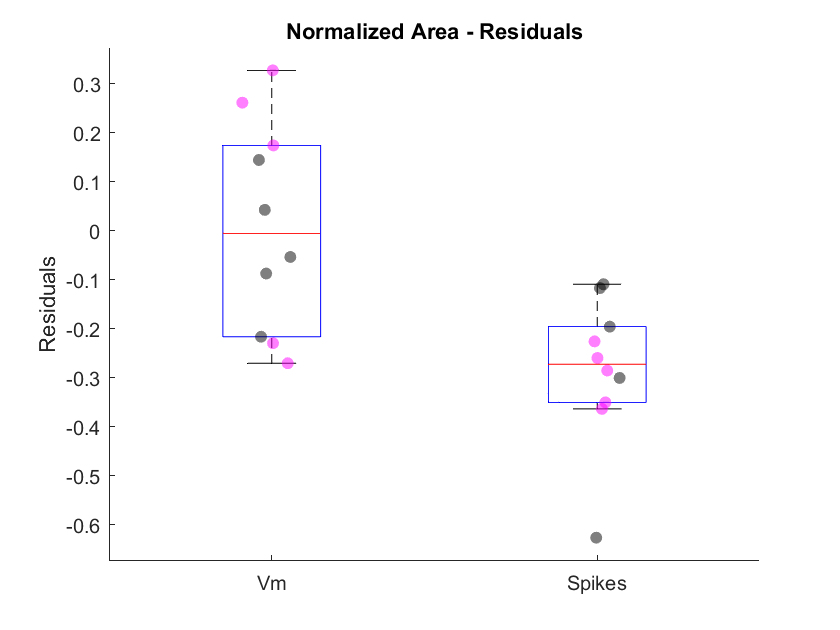

residualIndex = @(x,y) (y-x);%./(x+y));

groupIDs = zeros(1, numel([upFFVmDSI, downFFVmDSI, upFFSpikeDSI, downFFSpikeDSI]));
groupIDs(numel(upFFSpikeDSI) + numel(downFFSpikeDSI) + 1:end) = 1;

upVmResiduals = residualIndex(upFFVmNormedArea, upLowCVmNormedArea);
downVmResiduals = residualIndex(downFFVmNormedArea, downLowCVmNormedArea);

upSpikeResiduals = residualIndex(upFFSpikeNormedArea, upLowCSpikeNormedArea);
downSpikeResiduals = residualIndex(downFFSpikeNormedArea, downLowCSpikeNormedArea);

allResiduals = [upVmResiduals downVmResiduals, upSpikeResiduals, downSpikeResiduals];

figure
title('Normalized Area - Residuals')
hold on
boxplot(allResiduals, groupIDs, 'symbol', '')
%scatter Vm points
scatter(ones(size(upVmResiduals)).*(1+(rand(size(upVmResiduals))-0.5)/5),upVmResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals)).*(1+(rand(size(downVmResiduals))-0.5)/5),downVmResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter spike points
scatter(ones(size(upSpikeResiduals)).*(1+(rand(size(upSpikeResiduals))-0.5)/5) + 1,upSpikeResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downSpikeResiduals)).*(1+(rand(size(downSpikeResiduals))-0.5)/5) + 1,downSpikeResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
xticklabels({'Vm', 'Spikes'})
ylabel('Residuals')
box off

p = signrank([upVmResiduals, downVmResiduals], [upSpikeResiduals, downSpikeResiduals])

p = 0.0020

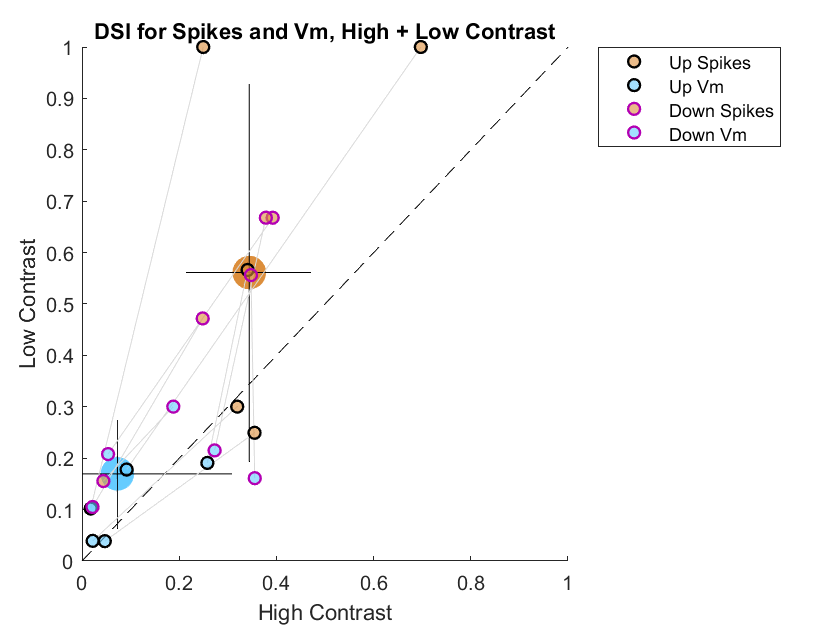

medianSpikeX = median([upFFSpikeDSI, downFFSpikeDSI]);
medianSpikeY = median([upLowCSpikeDSI downLowCSpikeDSI]);
xSpikeER = iqr([upFFSpikeDSI, downFFSpikeDSI]);
ySpikeER = iqr([upLowCSpikeDSI downLowCSpikeDSI]);

medianVmX = median([upFFVmDSI, downFFVmDSI]);
medianVmY = median([upLowCVmDSI, downLowCVmDSI]);
xVmER = iqr([upFFVmDSI, downFFVmDSI]);
yVmER = iqr([upLowCVmDSI, downLowCVmDSI]);


figure
title('DSI for Spikes and Vm, High + Low Contrast')
hold on

%Scatter medians for spikes and Vm
scatter(medianSpikeX, medianSpikeY, 300, 'MarkerEdgeColor', [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [220, 142, 59]/255, 'HandleVisibility', 'off') %spike median
plot([-xSpikeER, xSpikeER]+medianSpikeX, [medianSpikeY, medianSpikeY], 'k', 'HandleVisibility', 'off')
plot([medianSpikeX, medianSpikeX], [-ySpikeER, ySpikeER] + medianSpikeY, 'k', 'HandleVisibility', 'off')
scatter(medianVmX, medianVmY, 300, 'MarkerEdgeColor',  [1, 1, 1], 'LineWidth', 0.1, 'MarkerFaceColor', [101, 204, 255]/255, 'HandleVisibility', 'off') %Vm median
plot([-xVmER, xVmER]+medianVmX, [medianVmY, medianVmY], 'k', 'HandleVisibility', 'off')
plot([medianVmX, medianVmX], [-yVmER, yVmER] + medianVmY, 'k', 'HandleVisibility', 'off')

%plot unity line
plot([0, 1], [0, 1], '--k', 'HandleVisibility', 'off')

%plot lines connecting points from same cells first
for i = 1:size(upFFSpikeDSI, 2) %ups
    plot([upFFSpikeDSI(i) upFFVmDSI(i)], [upLowCSpikeDSI(i) upLowCVmDSI(i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
end

for i = 1:size(downFFSpikeDSI, 2) %downs
    plot([downFFSpikeDSI(i) downFFVmDSI(i)], [downLowCSpikeDSI(i) downLowCVmDSI(i)], 'Color', [0.85, 0.85, 0.85], 'MarkerSize', 0.1, 'HandleVisibility', 'off') %connect the points
end

%scastter points for each cell
%ups
scatter(upFFSpikeDSI, upLowCSpikeDSI, 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.6) %spike points
scatter(upFFVmDSI, upLowCVmDSI, 'MarkerEdgeColor','k', 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.6) %Vm points
%downs
scatter(downFFSpikeDSI, downLowCSpikeDSI, 'MarkerEdgeColor', [0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [220, 142, 59]/255, 'MarkerFaceAlpha', 0.6) %spike points
scatter(downFFVmDSI, downLowCVmDSI, 'MarkerEdgeColor',[0.7, 0, 0.7], 'LineWidth', 1.2, 'MarkerFaceColor', [101, 204, 255]/255, 'MarkerFaceAlpha', 0.6) %Vm points


l = legend({'Up Spikes', 'Up Vm', 'Down Spikes', 'Down Vm'});
l.Location = 'bestoutside';
xlim([0 1])
ylim([0, 1])
xlabel('High Contrast')
ylabel('Low Contrast')

p_Vm = signrank ([upFFVmDSI, downFFVmDSI], [upLowCVmDSI, downLowCVmDSI])

p_Vm = 0.3750

p_Spike = signrank ([upFFSpikeDSI, downFFSpikeDSI], [upLowCSpikeDSI, downLowCSpikeDSI])

p_Spike = 0.0098

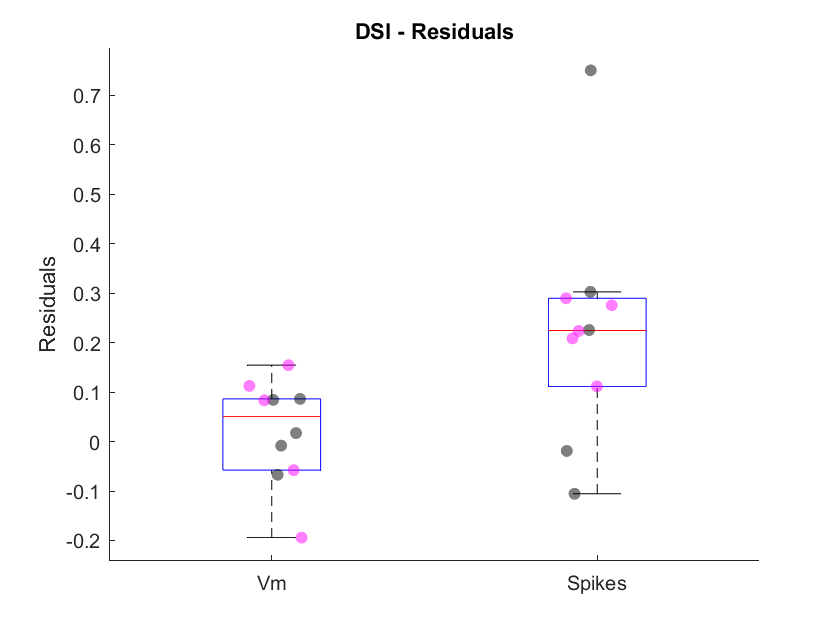

upVmResiduals = residualIndex(upFFVmDSI, upLowCVmDSI);
downVmResiduals = residualIndex(downFFVmDSI, downLowCVmDSI);

upSpikeResiduals = residualIndex(upFFSpikeDSI, upLowCSpikeDSI);
downSpikeResiduals = residualIndex(downFFSpikeDSI, downLowCSpikeDSI);

allResiduals = [upVmResiduals downVmResiduals, upSpikeResiduals, downSpikeResiduals];

figure
title('DSI - Residuals')
hold on
boxplot(allResiduals, groupIDs, 'symbol', '')
%scatter Vm points
scatter(ones(size(upVmResiduals)).*(1+(rand(size(upVmResiduals))-0.5)/5),upVmResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downVmResiduals)).*(1+(rand(size(downVmResiduals))-0.5)/5),downVmResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
%scatter spike points
scatter(ones(size(upSpikeResiduals)).*(1+(rand(size(upSpikeResiduals))-0.5)/5) + 1,upSpikeResiduals,'k','filled', 'MarkerFaceAlpha', 0.5)
scatter(ones(size(downSpikeResiduals)).*(1+(rand(size(downSpikeResiduals))-0.5)/5) + 1,downSpikeResiduals,'m','filled', 'MarkerFaceAlpha', 0.5)
xticklabels({'Vm', 'Spikes'})
ylabel('Residuals')
box off


p = signrank([upVmResiduals, downVmResiduals], [upSpikeResiduals, downSpikeResiduals])

p = 0.0273